% C_i Polynomial Calculation
A = [1, 1;
    -1, 3;]

A =      1     1
    -1     3



B = [-2;
    0]

B =     -2
     0



C = A \ B

C =    -1.5000
   -0.5000


% Trash Can
-8/9*(1+1/sqrt(10))

ans = -1.1700

-8/9*(1-1/sqrt(10))

ans = -0.6078

s = tf('s');
% System Define
sys = (4*s-8)/(s^2 + 2*s - 9)


sys =
 
     4 s - 8
  -------------
  s^2 + 2 s - 9
 
连续时间传递函数。


% sys = 10/(s^2 + 2*s + 10)

% DC Gain
GAIN = dcgain(sys)

GAIN = 0.8889


% Poles
p = pole(sys)

p =    -4.1623
    2.1623



% Satability
isStable = all(real(p)<0)

isStable = logical
   0


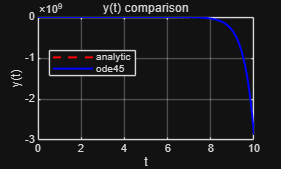

% Change Param
% HW2 b
% Check input response
p1 = -1 + sqrt(10);
p2 = -1 - sqrt(10);
c1 = -(8/9)*(1 + 1/sqrt(10));
c2 = -(8/9)*(1 - 1/sqrt(10));
cons = 16/9;

y_ana = @(t) c1*exp(p1*t) + c2*exp(p2*t) + cons;

a1 = 2;
a0 = -9;
b0 = -16;

f  = @(t,x) [ x(2);
              -a1*x(2) - a0*x(1) + b0 ];

x0 = [0; 0];
[t,X] = ode45(f, [0 10], x0);

y_ode = X(:,1);
ya    = y_ana(t);

figure;
plot(t, ya,  'r--','LineWidth',1.5); hold on;
plot(t, y_ode,'b'  ,'LineWidth',1.5); hold off;
grid on; xlabel('t'); ylabel('y(t)');
legend('analytic','ode45','Location','best');
title('y(t) comparison');

% Change Param
% HW2 b
% Check input response
p1 = -1;
p2 = -1;
c1 = -2;
c2 = -2/3;
cons = 2;

y_ana = @(t) exp(-t).*(c1*cos(3*t) + c2*sin(3*t)) + cons;

a1 = 2;
a0 = 10;
b0 = 20; 

f  = @(t,x) [ x(2); -a1*x(2) - a0*x(1) + b0 ];

x0 = [0; 0];

[t,X] = ode45(f, [0 10], x0)

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0003
    0.0006
    0.0009


X =          0         0
    0.0000    0.0001
    0.0000    0.0001
    0.0000    0.0002
    0.0000    0.0002
    0.0000    0.0005
    0.0000    0.0007
    0.0000    0.0010
    0.0000    0.0012
    0.0000    0.0025
    0.0000    0.0037
    0.0000    0.0050
    0.0000    0.0062
    0.0000    0.0125
    0.0000    0.0188


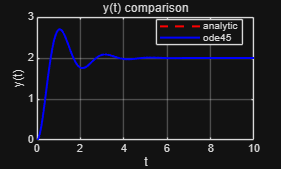


y_ode = X(:,1);
ya    = y_ana(t);

figure;
plot(t, ya,  'r--','LineWidth',1.5); hold on;
plot(t, y_ode,'b'  ,'LineWidth',1.5); hold off;
grid on; xlabel('t'); ylabel('y(t)');
legend('analytic','ode45','Location','best');
title('y(t) comparison');